ds = imageDatastore("Receipts"); % Creates an image datastore for all the image files in a folder
dataFilenames =ds.Files; % Accesses the Files property of the datastore ds
nFiles = numel(dataFilenames); % Finds the total number of files in datastore ds


for k = 1:nFiles % Iterates through all files in ds
    I = readimage(ds,k);
    isReceipt(k) = classifyImage(I);
    notReceipt(k) = ~ classifyImage(I);
end

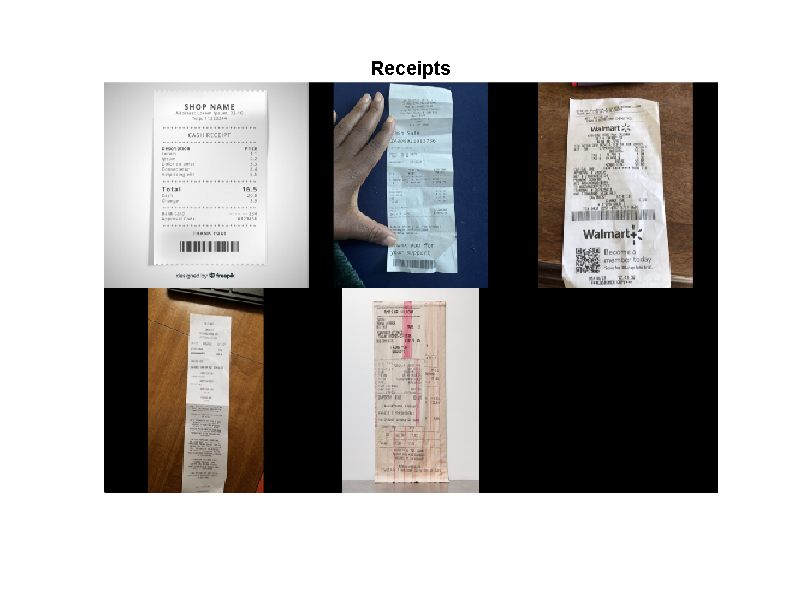

receiptFiles = ds.Files(isReceipt); % Index to extract the file names of the images classified as receipts
montage(receiptFiles) %Display all images classified as receipts
title("Receipts")

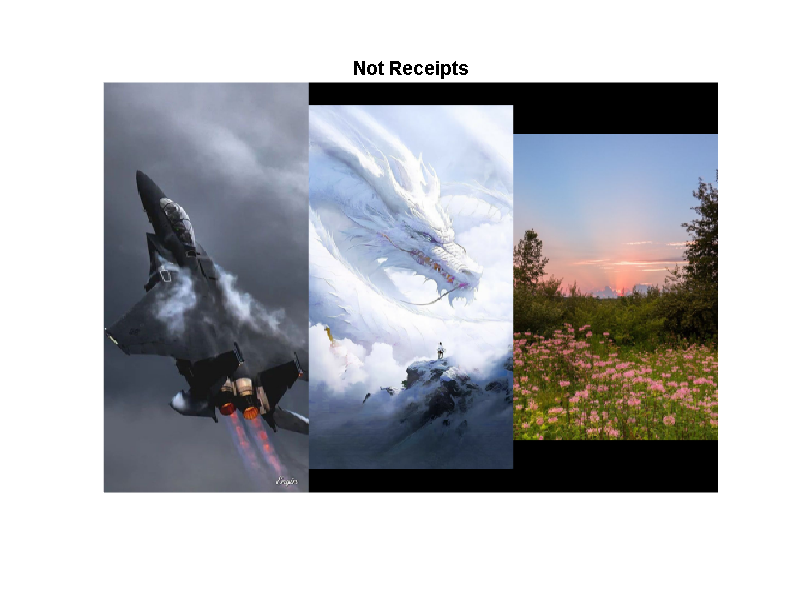


nonreceiptFiles = ds.Files(notReceipt); % Index to extract the file names of the images not classified as receipts
montage(nonreceiptFiles) %Display all images classified as receipts
title("Not Receipts")

function isReceipt = classifyImage(I)
    % This function processes an image and
    % classifies the image as receipt or non-receipt
    
    % Processing
    gs = im2gray(I); % Convert the image to grayscale
    gs = imadjust(gs); % Adjust the contrast of a grayscale image automatically
    
    H = fspecial("average",3); % Create a 3-by-3 averaging filter.
    gssmooth = imfilter(gs,H,"replicate"); % Apply the filter H to the grayscale image gs
    
    SE = strel("disk",8); % Create a "disk" structuring element with a radius of 8 pixels
    Ibg = imclose(gssmooth, SE); % Perform a closing operation on an image I with structuring element SE
    Ibgsub =  Ibg - gssmooth; % Subtracting Ibg from gs would result in negative intensities
    Ibw = ~imbinarize(Ibgsub); % To restore the original order, invert the image again
    
    SE = strel("rectangle",[3 25]); % Create a rectangular structuring element with a height of 3 pixels and a width of 25 pixels
    stripes = imopen(Ibw, SE); % To emphasize the dark text instead, perform the opposite operation and open the image
    
    signal = sum(stripes,2); % Analyze whether the opening operation has improved the image processing algorithm by plotting the row sum

    % Classification
    minIndices = islocalmin(signal,"MinProminence",75,"ProminenceWindow",25); 
    nMin = nnz(minIndices); % Count the number of minima
    isReceipt = nMin >= 9; % Define a cutoff value so the algorithm can classify an image as either a receipt or non-receipt
    
end